% ViterbiNet implementation in MATLAB Live Script
clear all;
close all;
clc;

rng(1);  % Set random seed for reproducibility

%% Parameters
CONST_SIZE = 2;      % BPSK
MEMORY_SIZE = 4;     % Channel memory

%% Helper Functions
function [x, s] = generate_symbols(n_samples, constellation_size)
    % Generate random symbols
    x = randi(constellation_size, 1, n_samples);
    % Convert to BPSK (-1, +1)
    s = 2 * (x - 0.5*(constellation_size+1));
end

function matrix = reshape_memory(signal, memory_size)
    % Reshape signal to include memory effects
    n_cols = length(signal);
    matrix = ones(memory_size, n_cols);
    
    for k = 1:memory_size
        l = memory_size - k + 1;
        if l <= n_cols
            matrix(l, 1:n_cols-l+1) = signal(l:n_cols);
        end
    end
end

function channel = generate_channel(exp_factor, memory_size)
    % Generate exponentially decaying channel
    channel = exp(-exp_factor * (0:memory_size-1));
end

function [x, channel, y] = generate_dataset(n_samples, snr_db, exp_factor, memory_size, constellation_size, channel_uncertainty, frame_size)
    if nargin < 6
        channel_uncertainty = 0;
    end
    if nargin < 7
        frame_size = 500;
    end
    
    % Generate symbols
    [x, s] = generate_symbols(n_samples, constellation_size);
    
    % Generate channel
    channel = generate_channel(exp_factor, memory_size);
    
    % Reshape signal
    memory_matrix = reshape_memory(s, memory_size);
    
    if channel_uncertainty > 0
        % Initialize received signal
        r = zeros(1, n_samples);
        
        % Process frame by frame
        n_frames = floor(n_samples/frame_size);
        for k = 1:n_frames
            start_idx = (k-1)*frame_size + 1;
            end_idx = k*frame_size;
            
            % Generate noisy channel
            channel_noise = sqrt(channel_uncertainty) * randn(size(channel)) * diag(channel);
            channel_est = channel + channel_noise;
            
            % Apply channel
            r(start_idx:end_idx) = fliplr(channel_est) * memory_matrix(:, start_idx:end_idx);
        end
        
        % Handle remaining samples
        if mod(n_samples, frame_size) ~= 0
            start_idx = n_frames*frame_size + 1;
            channel_noise = sqrt(channel_uncertainty) * randn(size(channel)) * diag(channel);
            channel_est = channel + channel_noise;
            r(start_idx:end) = fliplr(channel_est) * memory_matrix(:, start_idx:end);
        end
    else
        % Perfect CSI case
        r = fliplr(channel) * memory_matrix;
    end
    
    % Add noise
    sigma = 10^(-0.1 * snr_db);
    noise = sqrt(sigma) * randn(size(r));
    y = r + noise;
end


%% Visualize Channel Effects
% Generate a small sample of data to visualize
n_samples = 1000;
snr_db = 10;
exp_factor = 0.5;

% Generate channel
channel = generate_channel(exp_factor, MEMORY_SIZE);
fprintf('Channel Taps: [%.8f %.8f %.8f %.8f]\n', channel);

Channel Taps: [1.00000000 0.60653066 0.36787944 0.22313016]



% Generate symbols
[x, s] = generate_symbols(n_samples, CONST_SIZE);
fprintf('tx symbols: [%d %d %d ... %d %d %d]\n', s(1:3), s(end-2:end));

tx symbols: [-1 1 -1 ... 1 -1 1]



% Generate received signal
[~, ~, y] = generate_dataset(n_samples, snr_db, exp_factor, MEMORY_SIZE, CONST_SIZE);
fprintf('rx symbols: [%.8f %.8f %.8f ... %.8f %.8f %.8f]\n', y(1:3), y(end-2:end));

rx symbols: [1.84077042 0.60177703 -0.93477444 ... 1.25947669 2.01045566 1.59635808]


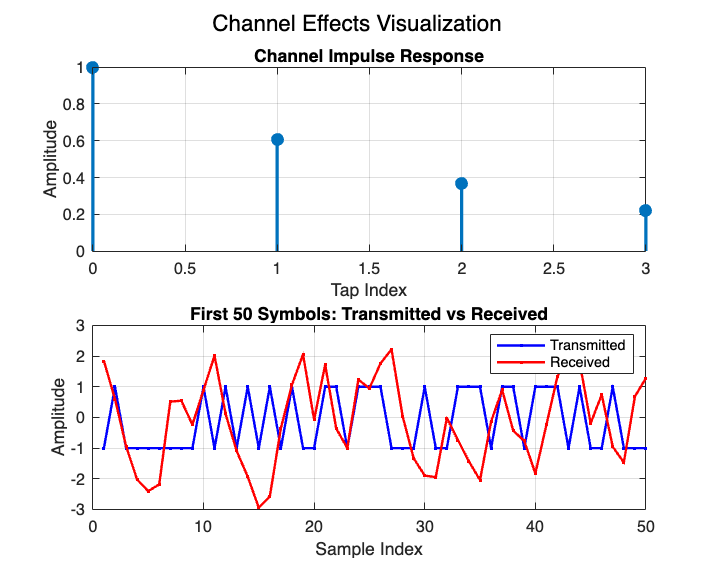


% Plot results
figure('Position', [100 100 1000 800]);

% Plot 1: Channel Response
subplot(2,1,1);
stem(0:MEMORY_SIZE-1, channel, 'filled', 'LineWidth', 2);
grid on;
xlabel('Tap Index');
ylabel('Amplitude');
title('Channel Impulse Response');

% Plot 2: Transmitted vs Received Signals
subplot(2,1,2);
plot(1:50, s(1:50), 'b.-', 'LineWidth', 1.5, 'DisplayName', 'Transmitted');
hold on;
plot(1:50, y(1:50), 'r.-', 'LineWidth', 1.5, 'DisplayName', 'Received');
grid on;
xlabel('Sample Index');
ylabel('Amplitude');
title('First 50 Symbols: Transmitted vs Received');
legend('show');
hold off;

% Add overall title
sgtitle('Channel Effects Visualization', 'FontSize', 14);


%% Neural Network Functions
function [net, GMModel] = train_viterbinet(x_train, y_train, constellation_size, memory_size)
    % Generate neural network
    inputSize = 1;
    numHiddenUnits = 100;
    numClasses = constellation_size^memory_size;
    
    % Create modified LSTM layer
    LSTMLayer = lstmLayer(numHiddenUnits,'OutputMode','last',...
        'RecurrentWeightsLearnRateFactor', 0,...
        'RecurrentWeightsL2Factor', 0);
    LSTMLayer.RecurrentWeights = zeros(4*numHiddenUnits,numHiddenUnits);
    
    % Create network layers
    layers = [...
        sequenceInputLayer(inputSize)
        LSTMLayer
        fullyConnectedLayer(floor(numHiddenUnits/2))
        reluLayer
        fullyConnectedLayer(numClasses)
        softmaxLayer
        classificationLayer];
    
    % Create memory matrix
    memory_matrix = reshape_memory(x_train, memory_size);
    
    % Convert memory matrix to state numbers
    v_fCombineVec = constellation_size.^(0:memory_size-1);
    state_numbers = v_fCombineVec * (memory_matrix - 1);
    v_fXcat = categorical(state_numbers');
    v_fYcat = num2cell(y_train');
    
    % Training options
    options = trainingOptions('adam',...
        'ExecutionEnvironment','auto',...
        'InitialLearnRate', 0.01,...
        'MaxEpochs', 100,...
        'MiniBatchSize', 27,...
        'GradientThreshold', 1,...
        'Verbose', false);
    
    % Train network
    net = trainNetwork(v_fYcat, v_fXcat, layers, options);
    
    % Train GMM
    GMModel = fitgmdist(y_train', constellation_size^memory_size, 'RegularizationValue', 0.1);
end

function x_hat = standard_viterbi(y_test, channel, const_size, memory_size, snr_db, channel_uncertainty)
    % Default channel_uncertainty to 0 if not provided
    if nargin < 6
        channel_uncertainty = 0;
    end
    
    n_states = const_size^memory_size;
    n_samples = length(y_test);
    
    % Compute noise variance
    sigma = 10^(-0.1 * snr_db);
    
    % Add channel uncertainty if specified
    if channel_uncertainty > 0
        channel_est = channel + sqrt(channel_uncertainty)*randn(size(channel))*diag(channel);
    else
        channel_est = channel;
    end
    
    % Compute conditional PDF for each state
    likelihood = zeros(n_samples, n_states);
    for i = 1:n_states
        % Convert state index to symbol sequence
        x = zeros(1, memory_size);
        idx = i - 1;  % Convert to 0-based for computation
        for j = 1:memory_size
            x(j) = mod(idx, const_size);
            idx = floor(idx / const_size);
        end
        
        % Convert to BPSK symbols (-1, +1)
        s = 2 * x - 1;
        
        % Compute expected output for this state using estimated channel
        expected_output = fliplr(channel_est) * s';
        
        % Compute Gaussian likelihood
        likelihood(:,i) = (1/sqrt(2*pi*sigma)) * exp(-0.5 * ((y_test - expected_output).^2) / sigma);
    end
    
    % Apply Viterbi algorithm
    x_hat = viterbi_decode(likelihood, const_size, memory_size);
end

function x_hat = viterbi_decode(likelihoods, const_size, memory_size)
    n_samples = size(likelihoods, 1);
    n_states = const_size^memory_size;
    x_hat = zeros(1, n_samples);
    
    % Generate trellis matrix
    trellis = zeros(n_states, const_size);
    for i = 1:n_states
        idx = mod(i-1, const_size^(memory_size-1));
        for j = 1:const_size
            trellis(i,j) = const_size * idx + (j-1) + 1;
        end
    end
    
    % Apply Viterbi
    costs = -log(likelihoods + 1e-12);  % Add small constant to avoid log(0)
    path_metrics = zeros(n_states, 1);
    
    for t = 1:n_samples
        next_metrics = zeros(n_states, 1);
        for i = 1:n_states
            temp = zeros(const_size, 1);
            for j = 1:const_size
                temp(j) = path_metrics(trellis(i,j)) + costs(t,i);
            end
            next_metrics(i) = min(temp);
        end
        
        path_metrics = next_metrics;
        [~, best_state] = min(path_metrics);
        x_hat(t) = mod(best_state-1, const_size) + 1;
    end
end


function x_hat = apply_viterbinet(y_test, net, GMModel, const_size, memory_size)
    % Get dimensions
    n_states = const_size^memory_size;
    
    % Get network predictions for state probabilities
    y_test_cell = num2cell(y_test');
    state_probs = predict(net, y_test_cell);
    
    % Get GMM probabilities
    output_probs = pdf(GMModel, y_test');
    
    % Compute final likelihoods
    likelihoods = state_probs .* output_probs * n_states;
    
    % Apply Viterbi algorithm using the helper function
    x_hat = viterbi_decode(likelihoods, const_size, memory_size);
end


%% Parameters
const_size = 2;      % BPSK
memory_size = 4;     % Channel memory
test_size = 50000;   % Test samples
% EXP_FACTOR = 0.5;    % Channel exponential decay


disp("Viterbi testing");

Viterbi testing



snr_range = 0:2:10;
exp_factors = 0.2:0.2:0.4;
channel_uncertainty = 0.1;
results.viterbi_certain = zeros(size(snr_range));
results.viterbi_uncertain = zeros(size(snr_range));

% Loop over exponential factors
for exp_idx = 1:length(exp_factors)
    exp_factor = exp_factors(exp_idx);
    fprintf('\nTesting exponential factor = %.1f\n', exp_factor);
    
    % Loop over SNR values
    for i = 1:length(snr_range)
        snr_db = snr_range(i);
        % fprintf('Testing SNR = %.1f dB\n', snr_db);
        
        % Generate test data
        [x_test, channel, y_test] = generate_dataset(test_size, snr_db, exp_factor, memory_size, const_size);
        
        % Test viterbi - certain, uncertain
        x_hat_viterbi_certain = standard_viterbi(y_test, channel, const_size, memory_size, snr_db, 0);
        results.viterbi_certain(i) = results.viterbi_certain(i) + mean(x_hat_viterbi_certain ~= x_test);
        x_hat_viterbi_uncertain = standard_viterbi(y_test, channel, const_size, memory_size, snr_db, channel_uncertainty);
        results.viterbi_uncertain(i) = results.viterbi_uncertain(i) + mean(x_hat_viterbi_uncertain ~= x_test);
    end
end


Testing exponential factor = 0.2

Testing exponential factor = 0.4


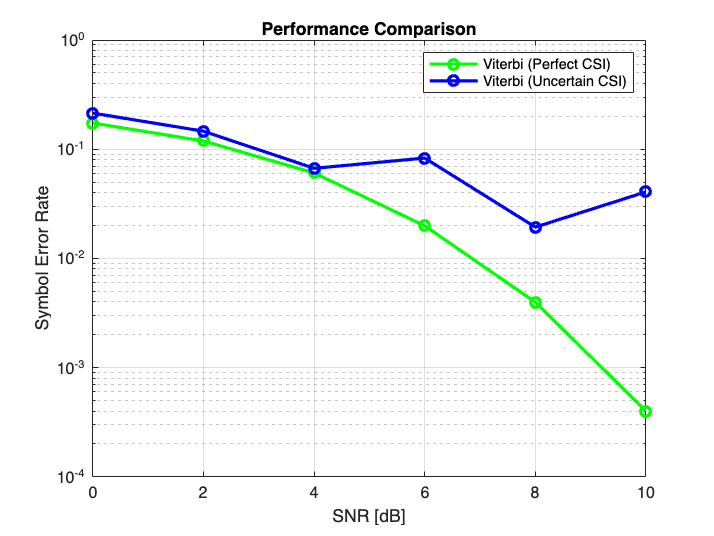

results.viterbi_uncertain = results.viterbi_uncertain/length(exp_factors);
results.viterbi_certain = results.viterbi_certain/length(exp_factors);

% Plot results
figure;
semilogy(snr_range, results.viterbi_certain, 'go-', 'LineWidth', 2, 'DisplayName', 'Viterbi (Perfect CSI)');
grid on;
hold on;
semilogy(snr_range, results.viterbi_uncertain, 'bo-', 'LineWidth', 2, 'DisplayName', 'Viterbi (Uncertain CSI)');
xlabel('SNR [dB]');
ylabel('Symbol Error Rate');
legend('show');
title('Performance Comparison');

%%% WARNING - TAKES VERY LONG TIME TO RUN

%% Parameters
const_size = 2;      % BPSK
memory_size = 4;     % Channel memory
train_size = 5000;   % Training samples
test_size = 50000;   % Test samples
SNR_DB = 10;         % SNR in dB
% EXP_FACTOR = 0.5;    % Channel exponential decay

% Run Test
snr_range = 0:2:10;
exp_factors = 0.2:0.2:0.5;
channel_uncertainty = 0.1;
frame_size = train_size/10;

% Initialize results storage
results.viterbinet_certain = zeros(size(snr_range));
results.viterbinet_uncertain = zeros(size(snr_range));

% Loop over exponential factors
for exp_idx = 1:length(exp_factors)
    exp_factor = exp_factors(exp_idx);
    fprintf('\nTesting exponential factor = %.1f\n', exp_factor);
    
    % Loop over SNR values
    for i = 1:length(snr_range)
        snr_db = snr_range(i);
        fprintf('Testing SNR = %.1f dB\n', snr_db);
        
        % Generate test data
        [x_test, ~, y_test] = generate_dataset(test_size, snr_db, exp_factor, memory_size, const_size);
        
        % Generate training data
        [x_train_certain, ~, y_train_certain] = generate_dataset(train_size, snr_db, exp_factor, memory_size, const_size, 0, 0);
        [x_train_uncertain, ~, y_train_uncertain] = generate_dataset(train_size, snr_db, exp_factor, memory_size, const_size, channel_uncertainty, frame_size);
        
        % Full CSI
        [net, GMModel] = train_viterbinet(x_train_certain, y_train_certain, const_size, memory_size);
        x_hat_certain = apply_viterbinet(y_test, net, GMModel, const_size, memory_size);
        results.viterbinet_certain(i) = results.viterbinet_certain(i) + mean(x_hat_certain ~= x_test);
        % fprintf('ViterbiNet Certain SER: %.4f\n', results.viterbinet_certain(i));

        % Uncertain CSI
        [net, GMModel] = train_viterbinet(x_train_uncertain, y_train_uncertain, const_size, memory_size);
        x_hat_uncertain = apply_viterbinet(y_test, net, GMModel, const_size, memory_size);
        results.viterbinet_uncertain(i) = results.viterbinet_uncertain(i) + mean(x_hat_uncertain ~= x_test);
        % fprintf('ViterbiNet Uncertain SER: %.4f\n', results.viterbinet_uncertain(i));

    end
end


Testing exponential factor = 0.2


Testing SNR = 0.0 dB


Testing SNR = 2.0 dB


Testing SNR = 4.0 dB


Testing SNR = 6.0 dB


Testing SNR = 8.0 dB


Testing SNR = 10.0 dB



Testing exponential factor = 0.4


Testing SNR = 0.0 dB


Testing SNR = 2.0 dB


Testing SNR = 4.0 dB
Testing SNR = 6.0 dB


Testing SNR = 8.0 dB
Testing SNR = 10.0 dB



results.viterbinet_uncertain = results.viterbinet_uncertain/length(exp_factors);
results.viterbinet_certain = results.viterbinet_certain/length(exp_factors);

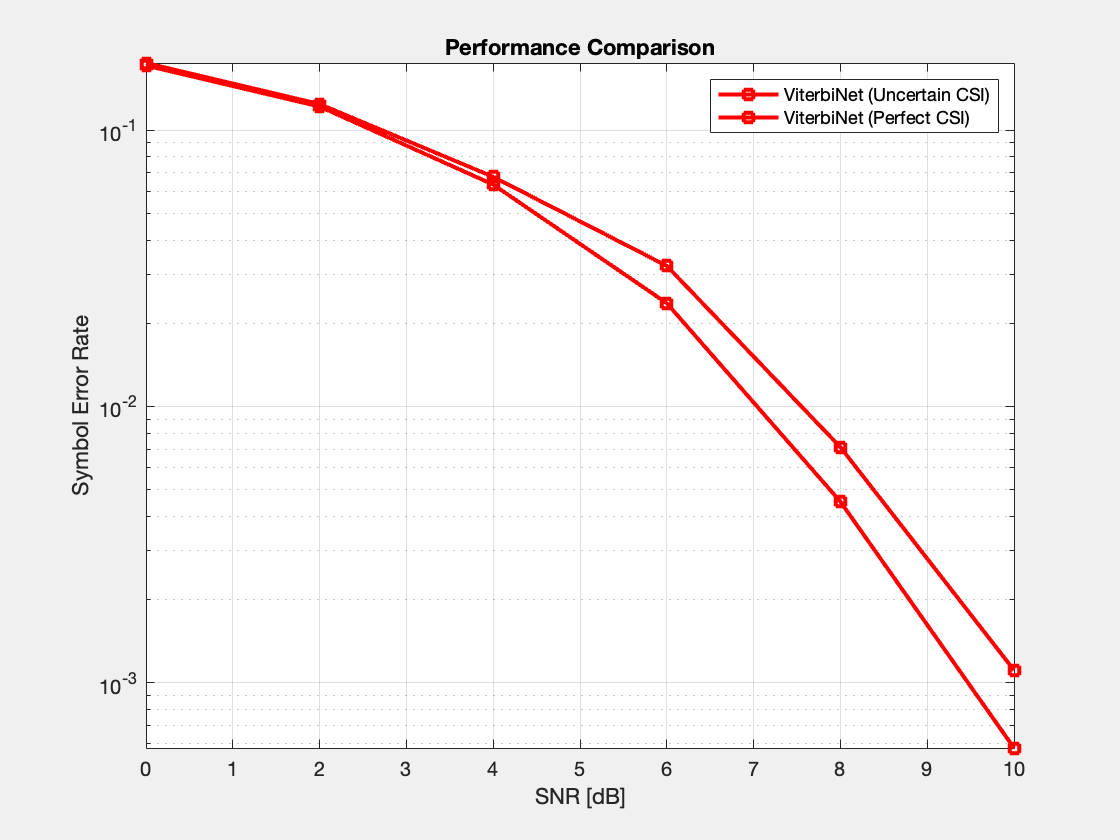

% results.viterbi_certain =  [0.1646 0.1094 0.0580 0.0214 0.0047 5.0000e-04]
% results.viterbi_uncertain =  [0.2247 0.1886 0.1418 0.1169 0.1491 0.1377]
% results.viterbinet_certain =  [0.1673 0.1117 0.0605 0.0228 0.0052 7.1000e-04]
% results.viterbinet_uncertain =  [0.1715 0.1226 0.0622 0.0255 0.0062 10.8000e-04]
% results.viterbinet_single_0db_certain =  [0.1738 0.1194 0.0701 0.0305 0.0098 0.0020]
% results.viterbinet_single_0db_uncertain =  [0.1734 0.1204 0.0706 0.0344 0.0127 0.0035]
% results.viterbinet_single_4db_certain =  [0.1682 0.1100 0.0612 0.0219 0.0044 3.8000e-04]
% results.viterbinet_single_4db_uncertain =  [0.1664 0.1146 0.0610 0.0224 0.0052 7.4000e-04]
% results.viterbinet_single_8db_certain =  [0.1926 0.1291 0.0654 0.0208 0.0040 5.6000e-04]
% results.viterbinet_single_8db_uncertain =  [0.1774 0.1156 0.0596 0.0251 0.0062 6.6000e-04]


% Plot results
figure;
semilogy(snr_range, results.viterbinet_uncertain, 'rs-', 'LineWidth', 2, 'DisplayName', 'ViterbiNet (Uncertain CSI)');
grid on;
hold on;
semilogy(snr_range, results.viterbinet_certain, 'rs-', 'LineWidth', 2, 'DisplayName', 'ViterbiNet (Perfect CSI)');
xlabel('SNR [dB]');
ylabel('Symbol Error Rate');
legend('show');
title('Performance Comparison');

% Plot all results
set(gcf,'Visible','on')

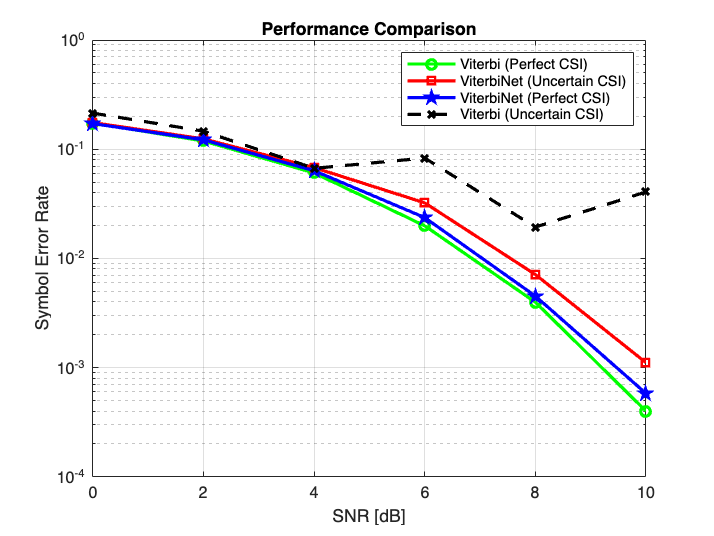

figure;
semilogy(snr_range, results.viterbi_certain, 'go-', 'LineWidth', 2, 'DisplayName', 'Viterbi (Perfect CSI)');
grid on;
hold on;
semilogy(snr_range, results.viterbinet_uncertain, 'rs-', 'LineWidth', 2, 'DisplayName', 'ViterbiNet (Uncertain CSI)');
semilogy(snr_range, results.viterbinet_certain, 'bp-', 'LineWidth', 2, 'DisplayName', 'ViterbiNet (Perfect CSI)');
semilogy(snr_range, results.viterbi_uncertain, 'blackx--', 'LineWidth', 2, 'DisplayName', 'Viterbi (Uncertain CSI)');
xlabel('SNR [dB]');
ylabel('Symbol Error Rate');
legend('show');
title('Performance Comparison');


%%% SINGLE SNR TESTING

%% Parameters
const_size = 2;      % BPSK
memory_size = 4;     % Channel memory
train_size = 5000;   % Training samples
test_size = 50000;   % Test samples
SNR_DB = 10;         % SNR in dB
exp_factor = 0.5;    % Channel exponential decay

% Run Test
snr_range = 0:2:10;
% exp_factors = 0.5:1:0.6;
channel_uncertainty = 0.1;
frame_size = train_size/10;

% Initialize results storage
results.viterbinet_single_0db_certain = zeros(size(snr_range));
results.viterbinet_single_0db_uncertain = zeros(size(snr_range));
results.viterbinet_single_4db_certain = zeros(size(snr_range));
results.viterbinet_single_4db_uncertain = zeros(size(snr_range));
results.viterbinet_single_8db_certain = zeros(size(snr_range));
results.viterbinet_single_8db_uncertain = zeros(size(snr_range));


% Loop over SNR values
snr_train_db = 0;
fprintf('Training SNR = %.1f dB\n', snr_train_db);

Training SNR = 0.0 dB



% Generate training data
[x_train_certain, ~, y_train_certain] = generate_dataset(train_size, snr_train_db, exp_factor, memory_size, const_size, 0, 0);
[x_train_uncertain, ~, y_train_uncertain] = generate_dataset(train_size, snr_train_db, exp_factor, memory_size, const_size, channel_uncertainty, frame_size);

% Full CSI
[net_0_certain, GMModel_0_certain] = train_viterbinet(x_train_certain, y_train_certain, const_size, memory_size);
for j = 1:length(snr_range)
    snr_test_db = snr_range(j);
    % Generate test data
    [x_test, ~, y_test] = generate_dataset(test_size, snr_test_db, exp_factor, memory_size, const_size);
    x_hat_certain = apply_viterbinet(y_test, net_0_certain, GMModel_0_certain, const_size, memory_size);
    results.viterbinet_single_0db_certain(j) = mean(x_hat_certain ~= x_test);
end
[net_0_uncertain, GMModel_0_uncertain] = train_viterbinet(x_train_uncertain, y_train_uncertain, const_size, memory_size);
for j = 1:length(snr_range)
    snr_test_db = snr_range(j);
    % Generate test data
    [x_test, ~, y_test] = generate_dataset(test_size, snr_test_db, exp_factor, memory_size, const_size);
    x_hat_uncertain = apply_viterbinet(y_test, net_0_uncertain, GMModel_0_uncertain, const_size, memory_size);
    results.viterbinet_single_0db_uncertain(j) = mean(x_hat_uncertain ~= x_test);
end

% Loop over SNR values
snr_train_db = 4;
fprintf('Training SNR = %.1f dB\n', snr_train_db);

% Generate training data
[x_train_certain, ~, y_train_certain] = generate_dataset(train_size, snr_train_db, exp_factor, memory_size, const_size, 0, 0);
[x_train_uncertain, ~, y_train_uncertain] = generate_dataset(train_size, snr_train_db, exp_factor, memory_size, const_size, channel_uncertainty, frame_size);

% Full CSI
[net_4_certain, GMModel_4_certain] = train_viterbinet(x_train_certain, y_train_certain, const_size, memory_size);
for j = 1:length(snr_range)
    snr_test_db = snr_range(j);
    % Generate test data
    [x_test, ~, y_test] = generate_dataset(test_size, snr_test_db, exp_factor, memory_size, const_size);
    x_hat_certain = apply_viterbinet(y_test, net_4_certain, GMModel_4_certain, const_size, memory_size);
    results.viterbinet_single_4db_certain(j) = mean(x_hat_certain ~= x_test);
end
[net_4_uncertain, GMModel_4_uncertain] = train_viterbinet(x_train_uncertain, y_train_uncertain, const_size, memory_size);
for j = 1:length(snr_range)
    snr_test_db = snr_range(j);
    % Generate test data
    [x_test, ~, y_test] = generate_dataset(test_size, snr_test_db, exp_factor, memory_size, const_size);
    x_hat_uncertain = apply_viterbinet(y_test, net_4_uncertain, GMModel_4_uncertain, const_size, memory_size);
    results.viterbinet_single_4db_uncertain(j) = mean(x_hat_uncertain ~= x_test);
end

% Loop over SNR values
snr_train_db = 8;
fprintf('Training SNR = %.1f dB\n', snr_train_db);

% Generate training data
[x_train_certain, ~, y_train_certain] = generate_dataset(train_size, snr_train_db, exp_factor, memory_size, const_size, 0, 0);
[x_train_uncertain, ~, y_train_uncertain] = generate_dataset(train_size, snr_train_db, exp_factor, memory_size, const_size, channel_uncertainty, frame_size);

% Full CSI
[net_8_certain, GMModel_8_certain] = train_viterbinet(x_train_certain, y_train_certain, const_size, memory_size);
for j = 1:length(snr_range)
    snr_test_db = snr_range(j);
    % Generate test data
    [x_test, ~, y_test] = generate_dataset(test_size, snr_test_db, exp_factor, memory_size, const_size);
    x_hat_certain = apply_viterbinet(y_test, net_8_certain, GMModel_8_certain, const_size, memory_size);
    results.viterbinet_single_8db_certain(j) = mean(x_hat_certain ~= x_test);
end
[net_8_uncertain, GMModel_8_uncertain] = train_viterbinet(x_train_uncertain, y_train_uncertain, const_size, memory_size);
for j = 1:length(snr_range)
    snr_test_db = snr_range(j);
    % Generate test data
    [x_test, ~, y_test] = generate_dataset(test_size, snr_test_db, exp_factor, memory_size, const_size);
    x_hat_uncertain = apply_viterbinet(y_test, net_8_uncertain, GMModel_8_uncertain, const_size, memory_size);
    results.viterbinet_single_8db_uncertain(j) = mean(x_hat_uncertain ~= x_test);
end


% Plot results
figure;
semilogy(snr_range, results.viterbinet_single_0db_certain, 'rs-', 'LineWidth', 2, 'DisplayName', 'ViterbiNet Single 0dB Perfect CSI');
grid on;
hold on;
semilogy(snr_range, results.viterbinet_single_0db_uncertain, 'rd--', 'LineWidth', 2, 'DisplayName', 'ViterbiNet Single 0dB Uncertain CSI)');
semilogy(snr_range, results.viterbinet_single_4db_certain, 'gd-', 'LineWidth', 2, 'DisplayName', 'ViterbiNet Single 4dB Perfect CSI');
semilogy(snr_range, results.viterbinet_single_4db_uncertain, 'go--', 'LineWidth', 2, 'DisplayName', 'ViterbiNet Single 0dB Uncertain CSI)');
semilogy(snr_range, results.viterbinet_single_8db_certain, 'bd-', 'LineWidth', 2, 'DisplayName', 'ViterbiNet Single 8dB Perfect CSI');
semilogy(snr_range, results.viterbinet_single_8db_uncertain, 'bo--', 'LineWidth', 2, 'DisplayName', 'ViterbiNet Single 8dB Uncertain CSI)');
semilogy(snr_range, results.viterbinet_certain, 'blacks-', 'LineWidth', 2, 'DisplayName', 'ViterbiNet SNR Specific Perfect CSI');
semilogy(snr_range, results.viterbinet_uncertain, 'blacko--', 'LineWidth', 2, 'DisplayName', 'ViterbiNet SNR Specific Uncertain CSI');
xlabel('SNR [dB]');
ylabel('Symbol Error Rate');
legend('show');
title('Performance Comparison');